# Computer Assignment #2

# PDE 

# Ali Hamzehpour 810100129

## Part 1 Solving Heat PDE

We want to solve this heat PDE in Matlab:

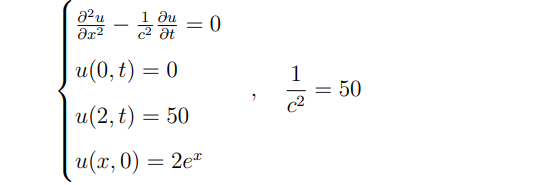

First we need to define our equation in Matlab. This part consists of three functions which can be seen at the end of the file.

### 1.4 Solving the Equation

Now we need to define a range for x, t(we divide x to 200 parts and t to 201 parts) then pass it to pdepe to solve the equation. Note that m should be 0 for our equation.

m = 0;
x1 = linspace(0,2,200);
t1 = linspace(0,10,201);
sol1 = pdepe(m,@heat_eq,@heat_eq_init,@heat_eq_bc,x1,t1);
u1 = sol1;

Next we plot the u-x plot at different times.

at t = 0 u(x) = ${2e}^x$ and also boundry conditions are set.

as time pass, disc conducts heat and plot is loosing mutations and becomes more linear.

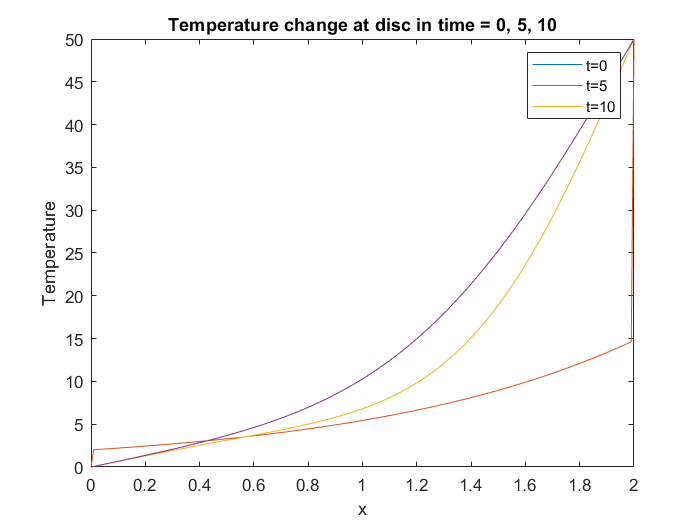

u1_t0 = sol1(1,:,:);
plot(x1,u1_t0)
hold("on")

u1_t5 = sol1(100,:,:);
plot(x1,u1_t5)

u1_t10 = sol1(201,:,:);
plot(x1,u1_t10)

xlabel('x')
ylabel('Temperature')
title('Temperature change at disc in time = 0, 5, 10')
legend("t=0","t=5","t=10");
hold("off")

Now we plot a 2d heatmap to show how the temperature changes as t or x changes.

At t = 0, The temperature suddenly becomes high at x = 2 but ss t gets bigger, the temperature from the boundries start to affect the other parts and make it more smooth.

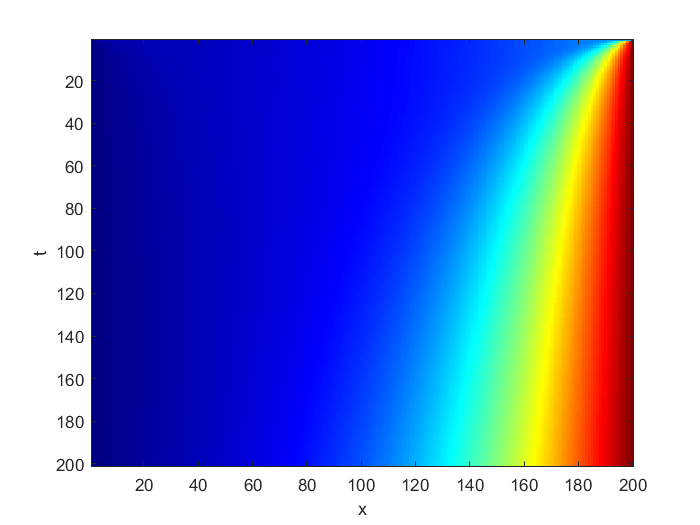

imagesc(sol1);
xlabel('x');
ylabel('t');
colormap("jet");

Then we plot the solutuon in 3d:

Again we can see at first the temperature is ${2e}^x$ for everywhere except the boundries the as time passes, temperature of parts of disc which are near to right BC is increasing and getting close to 50, and small part of disc near left BC is loosing temperature and getting close to 0. also, at any time, as we increase x, temp will be increased too, it means du/dx is ascending.

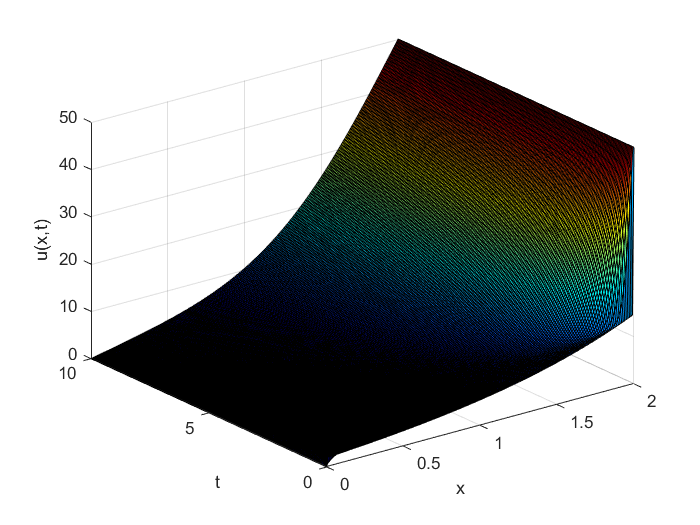

surf(x1,t1,u1)
xlabel('x')
ylabel('t')
zlabel('u(x,t)')

We repeat this whole proccess but this time we divide x to 100 parts and t to 101 parts. The result are the same but the plots are less precise than the last part.

m = 0;
x2 = linspace(0,2,100);
t2 = linspace(0,10,101);
sol2 = pdepe(m,@heat_eq,@heat_eq_init,@heat_eq_bc,x2,t2);
u2 = sol2(:,:,:);

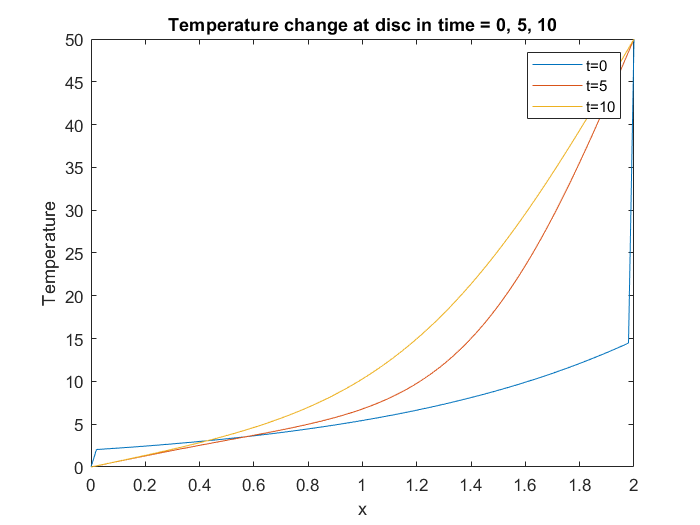

u2_t0 = sol2(1,:,:);
plot(x2,u2_t0)
hold("on")

u2_t5 = sol2(50,:,:);
plot(x2,u2_t5)

u2_t10 = sol2(101,:,:);
plot(x2,u2_t10)

xlabel('x')
ylabel('Temperature')
title('Temperature change at disc in time = 0, 5, 10')
legend("t=0","t=5","t=10");
hold("off")

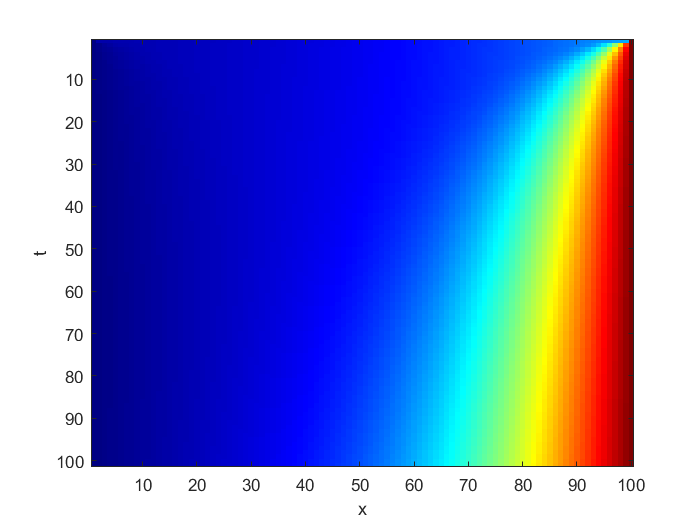

imagesc(sol2);
xlabel('x');
ylabel('t');
colormap("jet")

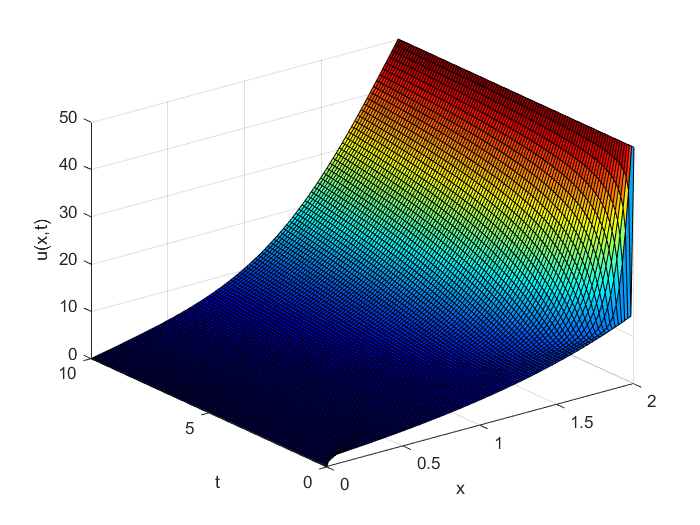

surf(x2,t2,u2)
xlabel('x')
ylabel('t')
zlabel('u(x,t)')

## Part 2 Solving Helmholtz Equation

This is the form of the Helmholtz equation:

And after doing the steps noted in the description, we can get the result:

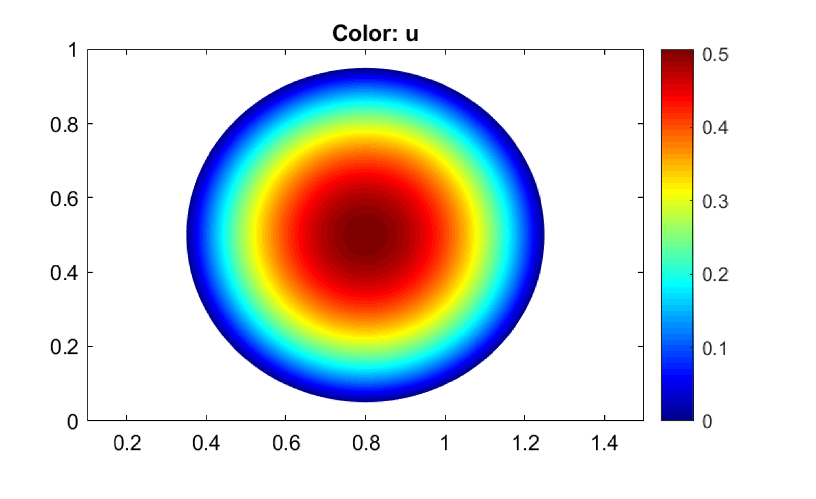

This is the time-indepent form of wave equation and The real solotion for BC is zero. As it can be seen from the plot, the more we go toward the center of the disk, the higher temeperature becomes. Also our equation is symmetrical to x and y so the solution is also symmetrical as can be seen in the plot.

## Functions for Defining Heat Equation

### 1.1 General PDE Form in Matlab

This is the form of a PDE in Matlab:

In order to form our own equation we set the functions as below:


$$c=50,m=0,f=\frac{\textrm{du}}{\textrm{dx}},s=0$$


function [c,f,s] = heat_eq(x,t,u,dudx)
    c = 50;
    f = dudx;
    s = 0;
end

### 1.2 Initial Conditions

Then we write a function to set our initial condition:

function init_val = heat_eq_init(x)
    init_val = 2*exp(x);
end

### 1.3 Boundry Conditions

The form of the boundry condition in Matlab is as follows:

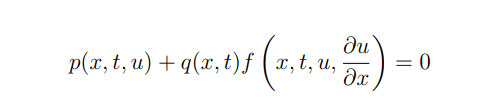

So for our equation, $q
$ is always 0 and $p

$ is set to $u - value$ in each right and left conditions.

function [pl,ql,pr,qr] = heat_eq_bc(xl,ul,xr,ur,t)
    pl = ul - 0; 
    ql = 0; 
    pr = ur - 50;
    qr = 0; 
end